# microCAT_compare_cal

Compare pre-deploymet and post-recovery microCATS

Author: Lewis Drysdale. 2021

clearvars; close('all');
indir   =('M:\Mar_Phys\Moorings\PRIZE moorings\data\moor_raw'); 
plot_dir = 'M:\Mar_Phys\Moorings\PRIZE moorings\figures';

calist=[7294;7289;7290;7291;7292;7295;9382];

for ii=1:numel(calist)
    
    % check what date formate is required for files 
    filecheck= [indir filesep '2018' filesep 'SBE37SM-RS232_0370' num2str(calist(ii)) '_2019_11_19.hex'];
    
    if exist(filecheck,'file')==2
        fdate='2019_11_19';
    else
        fdate='2019_11_25';
    end
    
    fl1 = [indir filesep '2018' filesep 'SBE37SM-RS232_0370'  num2str(calist(ii))   '_' fdate '_precal.cnv'];
    
    fid = fopen(fl1);
    tline = fgetl(fid);
    lineCounter = 1;
    while ischar(tline)
        if strcmp(tline, '*END*')
            break;
        end
        % Read next line
        tline = fgetl(fid);
        lineCounter = lineCounter + 1;
    end
    fclose(fid);
            
    [~,timeJ1,pres1,temp1,cond1,depth1,sal1,dens1,flag1]=textread(fl1,...
                '%f%f%f%f%f%f%f%f%f','headerlines',lineCounter);
            
    fl2 = [indir filesep '2018' filesep 'SBE37SM-RS232_0370' num2str(calist(ii)) '_' fdate '_postcal.cnv'];
    
    fid = fopen(fl2);
    tline = fgetl(fid);
    lineCounter = 1;
    while ischar(tline)
        if strcmp(tline, '*END*')
            break;
        end
        % Read next line
        tline = fgetl(fid);
        lineCounter = lineCounter + 1;
    end
    fclose(fid);
    
    [~,timeJ2,pres2,temp2,cond2,depth2,sal2,dens2,flag2]=textread(fl2,...
                '%f%f%f%f%f%f%f%f%f','headerlines',lineCounter);

     mtime=datenum('31-Dec-2017 00:00:00')+timeJ1;           

Set the recovery date for trimming axis

    start_date=datenum('22-Jun-2018 12:30:00');
    end_date=datenum('18-Nov-2019 00:00:00'); 
    id = mtime>=start_date & mtime<=end_date;

    Plot data along same axis    

    figure(ii);
    sgtitle(['Instrument ' num2str(calist(ii))]);
    ax(1)=subplot(311);
    h1=plot(mtime(id),pres1(id),'r-');
    hold on
    h2=plot(mtime(id),pres2(id),'b-');
    ylabel('Pressure')
    xlim([start_date end_date]);
    datetick('x');
    
    ax(2)=subplot(312);
    h1=plot(mtime(id),temp1(id),'r-');
    hold on
    h2=plot(mtime(id),temp2(id),'b-');
    ylabel('Temperature')      
    xlim([start_date end_date]);
    datetick('x');
    
    ax(3)=subplot(313);
    h1=plot(mtime(id),sal1(id),'r-');
    hold on
    h2=plot(mtime(id),sal2(id),'b-');
    ylabel('Salinity')        
    legend([h1 h2],{'Un-calibrated','Caliibrated'})
    xlim([start_date end_date]);
    datetick('x');
    
    width=20; height=25; FS=12; FN='Arial';
    for kk=1:numel(ax)
        xlabel(ax(kk),'Time');  
        set(ax(kk),'fontsize', FS, 'FontName',FN);
    end
    
    set(figure(ii),'units','centimeters','position',[1 1 width height])
    savename=[plot_dir filesep num2str(calist(ii)) '-calibration-compare'];
    print(figure(ii), '-dpng',savename);
    

Plot difference in values post vs. pre cal

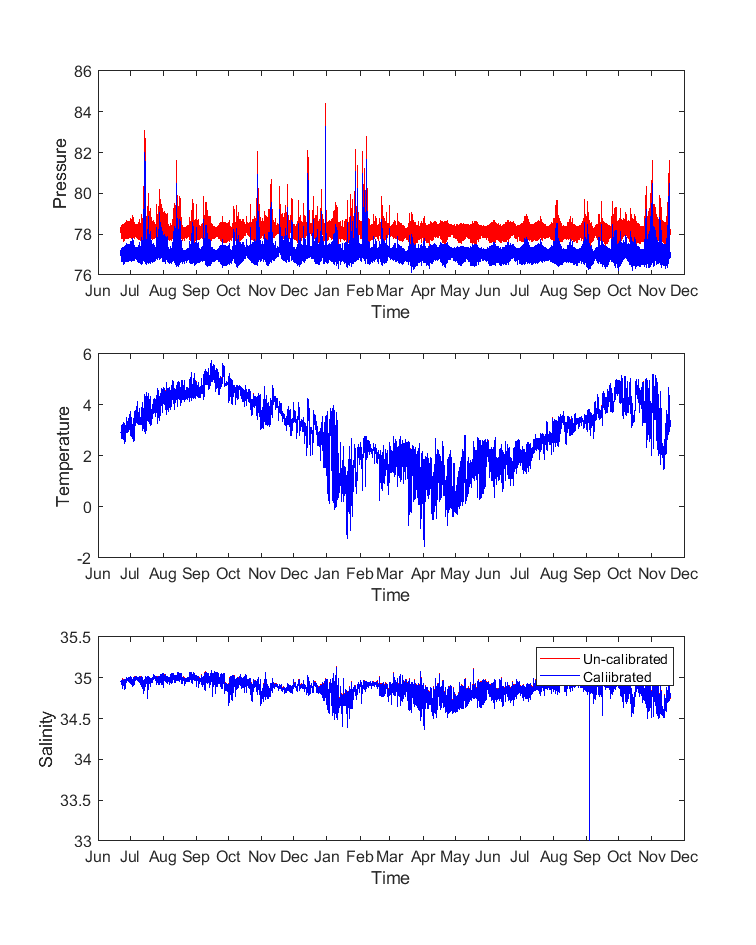

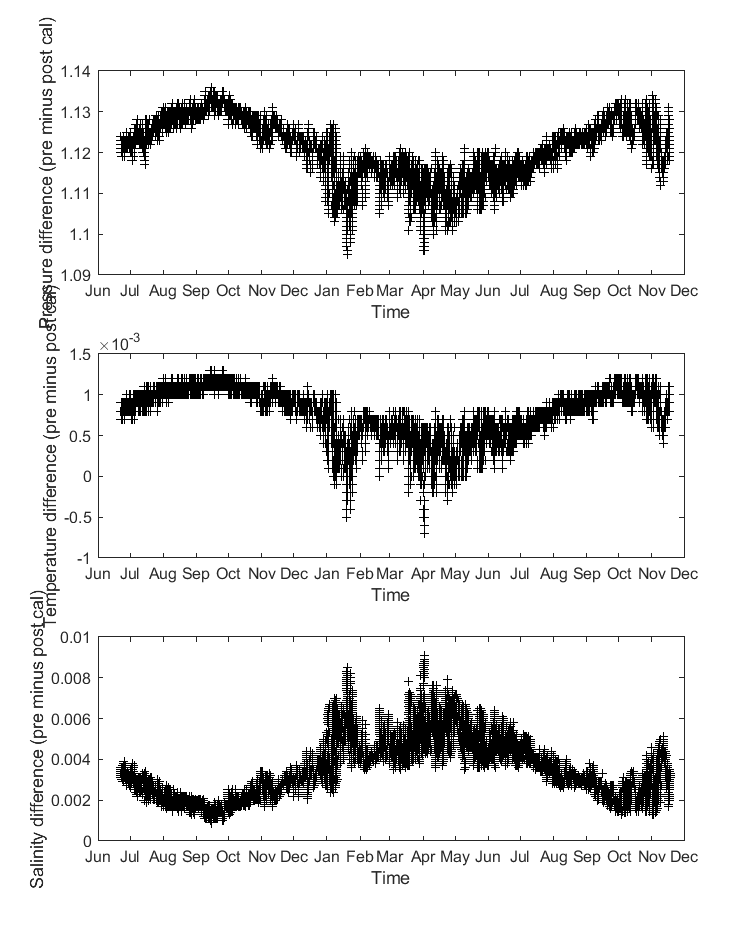

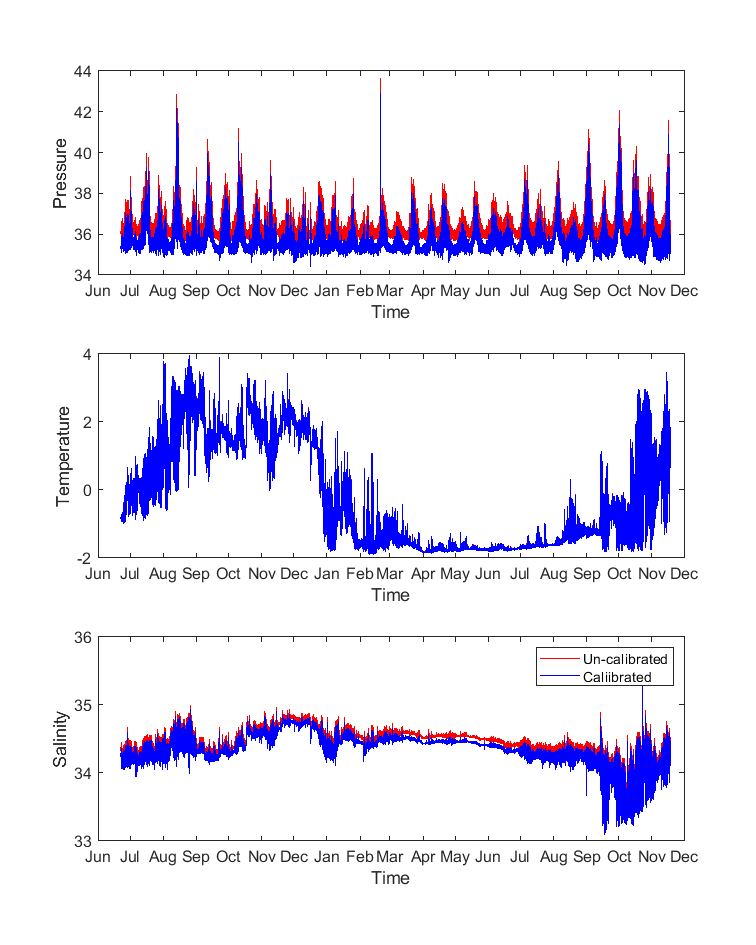

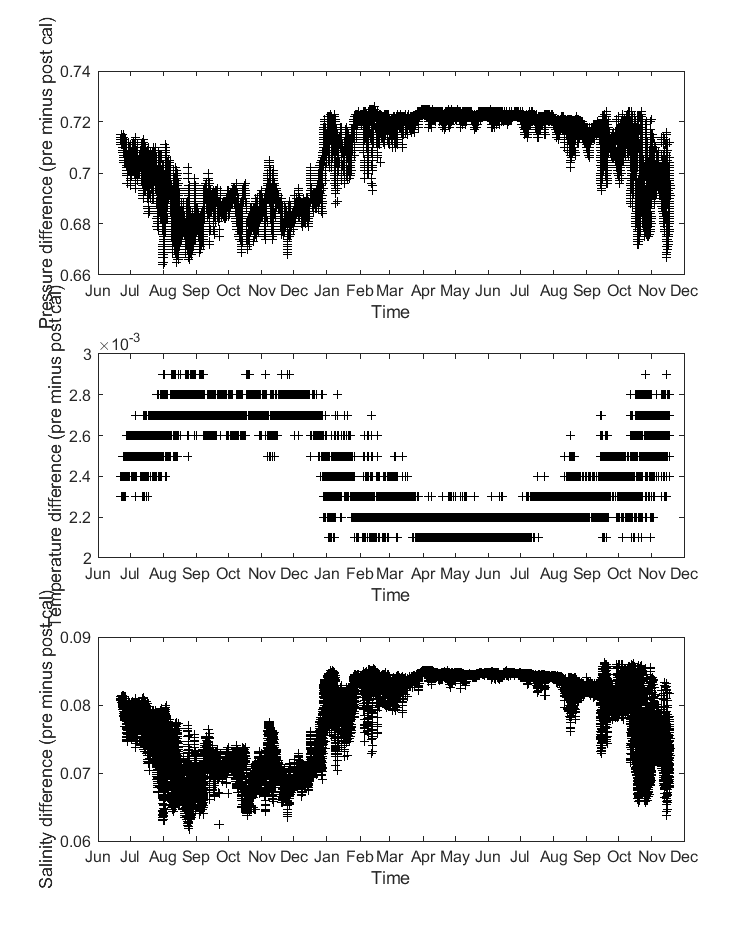

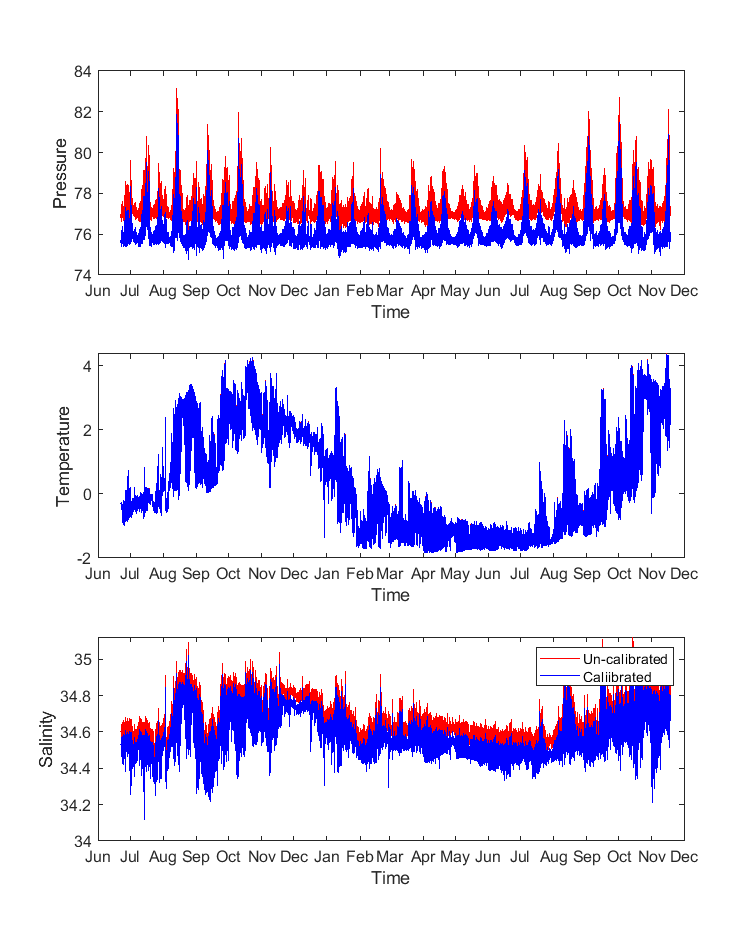

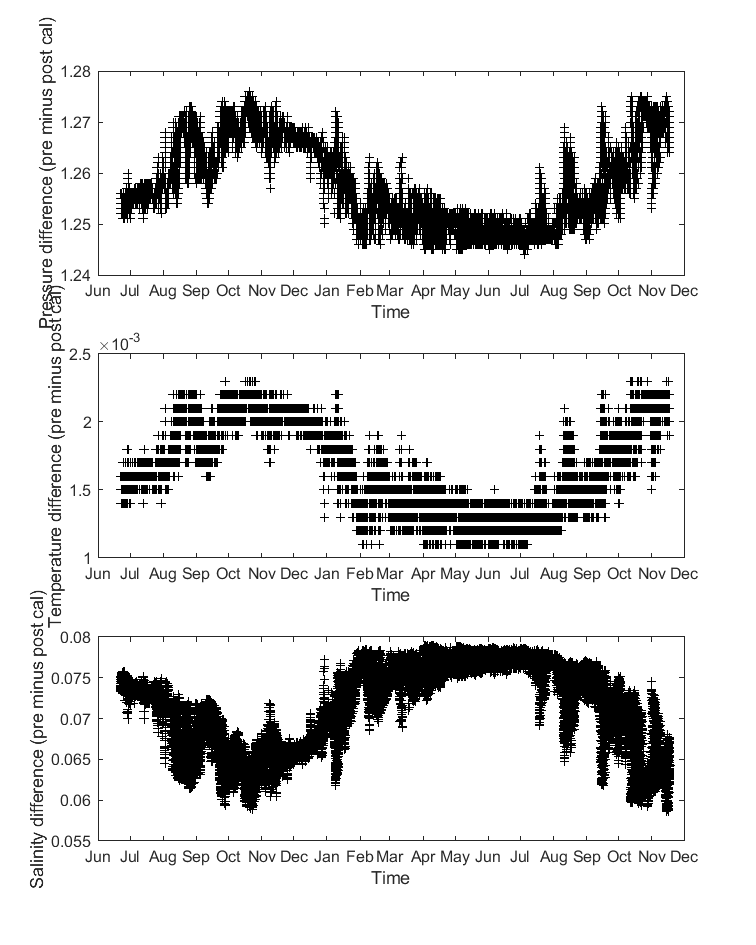

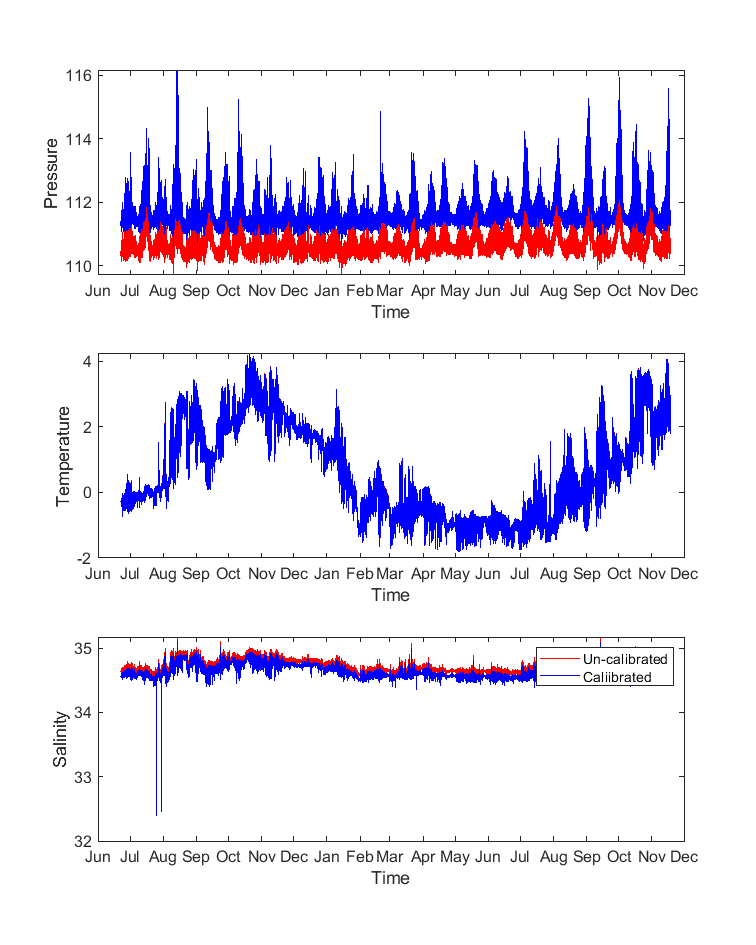

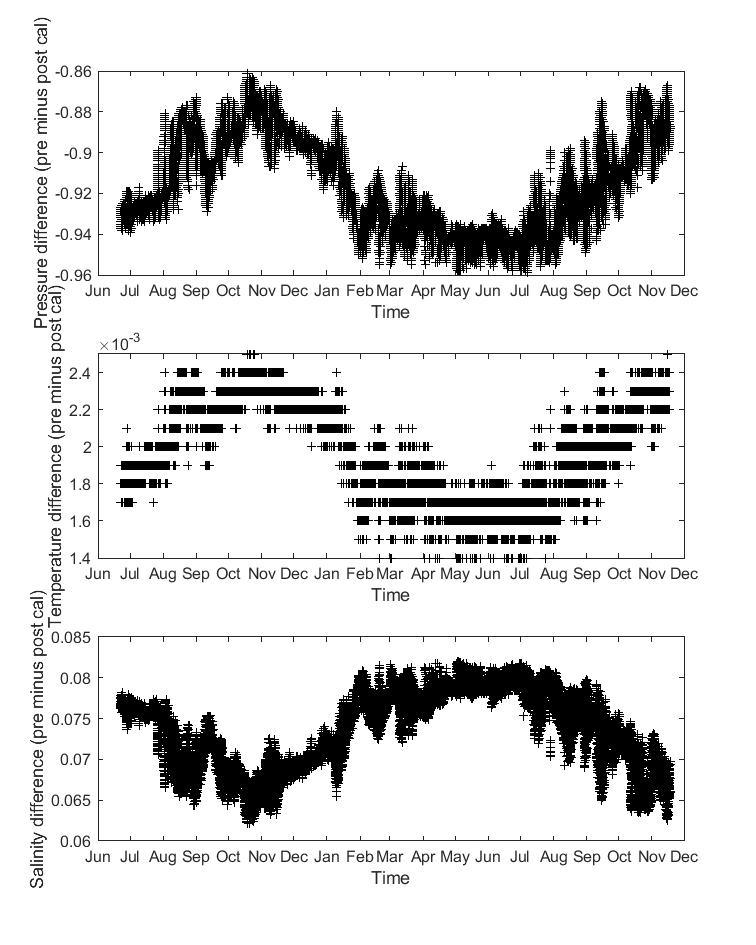

    
    figure(numel(calist)+ii);
    sgtitle(['Instrument ' num2str(calist(ii))]);
    ax(1)=subplot(311);
    h1=plot(mtime(id),pres1(id)-pres2(id),'k+');
    ylabel('Pressure difference (pre minus post cal)');
    xlim([start_date end_date]);
    datetick('x');
    
    ax(2)=subplot(312);
    h1=plot(mtime(id),temp1(id)-temp2(id),'k+');
    ylabel('Temperature difference (pre minus post cal)');    
    xlim([start_date end_date]);
    datetick('x');
    
    ax(3)=subplot(313);
    h1=plot(mtime(id),sal1(id)-sal2(id),'k+');
    ylabel('Salinity difference (pre minus post cal)');  
    xlim([start_date end_date]);
    datetick('x');
    
    for kk=1:numel(ax)
        xlabel(ax(kk),'Time');  
        set(ax(kk),'fontsize', FS, 'FontName',FN);
    end    
    set(figure(numel(calist)+ii),'units','centimeters','position',[1 1 width height])
    savename=[plot_dir filesep num2str(calist(ii)) '-calibration-difference'];
    print(figure(numel(calist)+ii), '-dpng',savename);   
    
end